# Data Preprocessing and Factor Creation

Copyright (c) 2018, MathWorks, Inc.

**Disclaimer: **We do not advocate for any technical indicators. Factors below are just examples of how you could incorpoate these indicators into mahcine/deep learning models. More information about functions for creating technical indicators can be found [here](https://www.mathworks.com/help/finance/introduction-4.html).

**Video**: [https://www.mathworks.com/videos/machine-learning-applications-in-risk-management-forecasting-bitcoin-volatility-using-the-regression-learner-app-1536231842528.html](https://www.mathworks.com/videos/machine-learning-applications-in-risk-management-forecasting-bitcoin-volatility-using-the-regression-learner-app-1536231842528.html) 

System requirements

- [MATLAB® R2018b](https://www.mathworks.com/products/matlab.html)

- [Financial Toolbox™](https://www.mathworks.com/products/finance.html)

- [Statistics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html)

Load data, which is generated from getQuandlData.mlx

load data/rawData.mat

**Generate technical indicator**

Generate n-day momentum and remove the original factors, except MKPRU (price).

nDay1 = [7, 15, 30];
symbol = T.Properties.VariableNames;
for i = 2:numel(symbol)
    for j = 1:numel(nDay1)
        factorName1 = [symbol{i} '_momentum' num2str(nDay1(j))];
        T.(factorName1) = tsmom(T.(symbol{i}),'NumPeriods',nDay1(j));
    end
    if i > 2
        T.(symbol{i}) = []; % Remove the original factors
    end
end

Convert price to n-day returns and volatility

nDay2 = [1, 5, 10, 20];
for i = 1:numel(nDay2)
    factorName2 = ['ret' num2str(nDay2(i))];
    T.(factorName2) = nDayReturn(T.MKPRU, nDay2(i));
end

nDay3 = [10, 30, 60, 180];
for i = 1:numel(nDay3)
    d = nDay3(i);
    factorName3 = ['vol' num2str(d)];
    T.(factorName3) = movstd(T.ret1, [d-1, 0])*sqrt(365/(d));
end

**Generate response variable (Y)**

Set the response variable to be 10-day volatility

nDay4 = 10;
ret2 = [T.ret1(2:end); NaN];
T.Response = movstd(ret2, [0,nDay4-1])*sqrt(365/nDay4);

## Split data into training and testing datasets

Remove variables that we are planning not to use

T.Time = [];

Split data into:

- data1_train: training data

- data2_test: testing data

T = rmmissing(T);
testSize = 365;
data1_train = T(1:end-testSize,:);
data2_test = T(end-testSize+1:end,:);

Preview training data

y = data1_train.Response;
mean_train = mean(y)

mean_train = 0.1878

sd_train = std(y)

sd_train = 0.1348

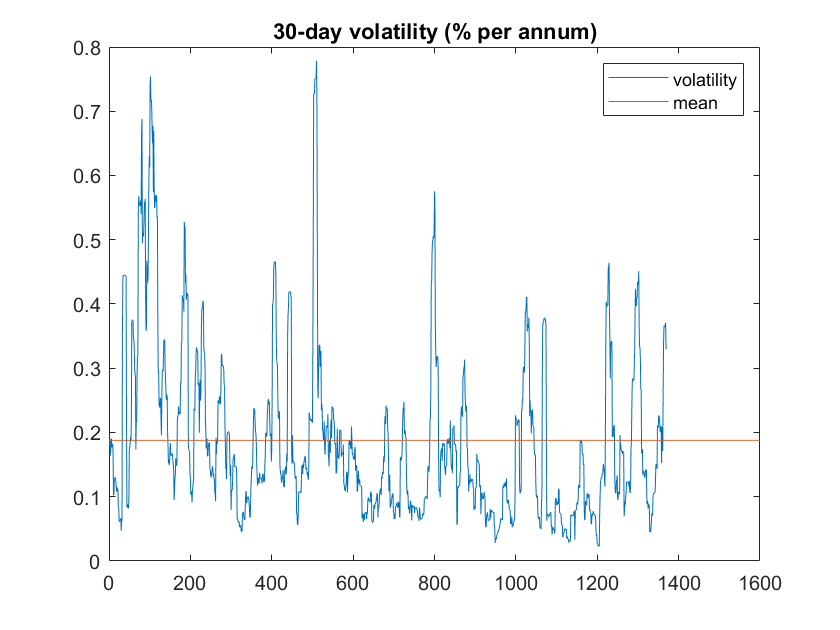

plot(y)
title('30-day volatility (% per annum)')
hold on
plot([0,1600],[mean_train, mean_train])
legend({'volatility','mean'})

Save data

clearvars -except data1_train data2_test
if exist('data') ~= 7
    mkdir('data');
end
save data/bitCoinData.mat

## Supporting functions

function returns = nDayReturn(prices, nDay)
% This function generates nDay return give the price vector
returns = NaN(size(prices,1),1);
returns(nDay+1:end) = prices(nDay+1:end) ./ prices(1:end-nDay) - 1;
end